## Cvičení 1 - seznámení:

Dneksa si ukážeme úvod do MATLABu, prostředí, proměnné a ukážeme v čem je MATLAB super.

Case sensitive:

A = 5

A = 5

a = 6

a = 6

Typy proměných?

b = int16(a)

b = int16
6

b = int8(a)

b = int8
6

b = '+'         % apostrofy = char   

b = '+'

b = "Ahoj"      % uvozovky = string

b = "Ahoj"

Who/s:

who


Your variables are:

A  a  b  



whos

  Name      Size            Bytes  Class     Attributes

  A         1x1                 8  double              
  a         1x1                 8  double              
  b         1x1               150  string              



Výpis na obrazovku

disp(b)

Ahoj


b

b = "Ahoj"

Pojmenování proměnné:

% 1a = 4;   hází chybu, proměná nesmí začínat číslicí
jinak = 5

jinak = 5

Pozor na klíčová slova v názvu proměnné:

pi      % Ludolfovo číslo

ans = 3.1416

ans     % poslední neuložený výpočet 

ans = 3.1416

inf     % nekonečno

ans = Inf

NaN     % není číslo 0/0

ans = NaN

ans 

ans = NaN

clock   % hodiny

ans = 	1.0e+03 *

    2.0220    0.0020    0.0190    0.0020    0.0160    0.0414


date    % datum

ans = '19-Feb-2022'

tic 
toc

Elapsed time is 0.002198 seconds.


Komplexní čísla:

1  + 2i

ans = 1.0000 + 2.0000i

i

ans = 0.0000 + 1.0000i

c = 2*i

c = 0.0000 + 2.0000i

Vektor:

a = [1, 2, 3]

a =      1     2     3


a = [1 2 3]     % mezery a čárky jsou totéž

a =      1     2     3


a+a

ans =      2     4     6


a.*a

ans =      1     4     9


Matice:

A = [1 2 3; 4 5 6]

A =      1     2     3
     4     5     6


2.*A

ans =      2     4     6
     8    10    12


A = [1 2 3; 4 5 6; 7 8 9]

A =      1     2     3
     4     5     6
     7     8     9


% A = [1 2 3; 4 5]      % chyba ve velikosti matice

Základní funkce:

sin(pi/2)   % sinus

ans = 1

cos(pi/2)   % cosinus

ans = 6.1232e-17

abs(-5)     % absolutní hodnota

ans = 5

sqrt(4)     % odmocnina

ans = 2

3^2         % mocnina

ans = 9

Další funkce:

length(a)   % délka vektoru

ans = 3

size(A)     % velikost matice

ans =      3     3


size(A,1)   % velikost matice v jedné dimenzi (počet řádků)

ans = 3

size(A,2)

ans = 3


min(a)      % nejmenší hodnota ve vektoru

ans = 1

max(a)      % největší hodnota ve vektoru

ans = 3


min(min(A))      % nejmenší hodnota v matici

ans = 1

max(max(A))      % největší hodnota v matici

ans = 9

Základní matice:

zeros(3)        % matice plná nul

ans =      0     0     0
     0     0     0
     0     0     0


zeros(1,3)      % vektor plný nul

ans =      0     0     0


zeros(3,1)

ans =      0
     0
     0



ones(3)         % samé jedničky

ans =      1     1     1
     1     1     1
     1     1     1


eye(3)          % jednotková matice

ans =      1     0     0
     0     1     0
     0     0     1


rand(3)         % náhodná čísla 0 až 1

ans =     0.8147    0.9134    0.2785
    0.9058    0.6324    0.5469
    0.1270    0.0975    0.9575



rand(3).*10         % náhodná čísla 0 až 10

ans =     9.6489    9.5717    1.4189
    1.5761    4.8538    4.2176
    9.7059    8.0028    9.1574


rand(3).*10+5         % náhodná čísla 5 až 15

ans =    12.9221    5.3571   11.7874
   14.5949   13.4913   12.5774
   11.5574   14.3399   12.4313


Vytvoření vektoru:

a = [1 2 3]

a =      1     2     3


b = 1:3

b =      1     2     3


b = 5:10

b =      5     6     7     8     9    10


b = 0:0.2:1

b =          0    0.2000    0.4000    0.6000    0.8000    1.0000


linspace(1,10,5) % vektor (od do, počet hodnot)

ans =     1.0000    3.2500    5.5000    7.7500   10.0000


První graf!

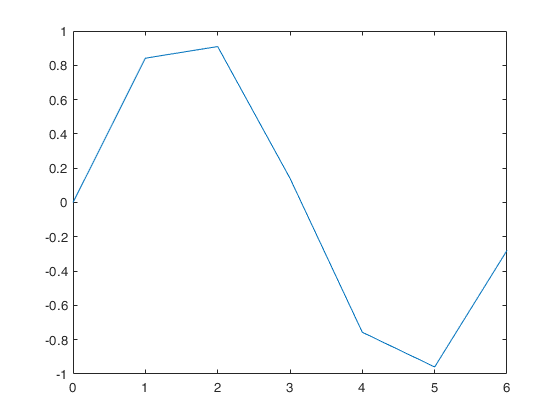

x = 0:2*pi;      % vektor od nuly do dvou pi
y = sin(x);      % sinus pro hodnoty vektoru x
plot(x,y)       % graf

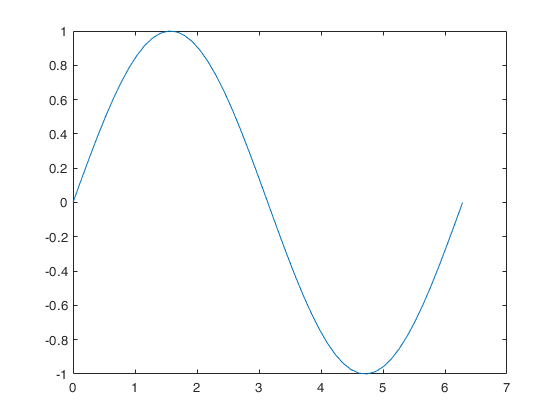


x = linspace(0,2*pi,50);      % vektor od nuly do dvou pi
y = sin(x);      % sinus pro hodnoty vektoru x
plot(x,y)       % graf

Odkazování na prvky matice/vektoru:

a

a =      1     2     3


A

A =      1     2     3
     4     5     6
     7     8     9



a(2)

ans = 2

A(2,3)

ans = 6

A(1,:)

ans =      1     2     3


A(:,3)

ans =      3
     6
     9


A(2:3,:)

ans =      4     5     6
     7     8     9


A(1,1:2)

ans =      1     2


A(:,[1,3])

ans =      1     3
     4     6
     7     9



A(A>5) = 0      % změní A!

A =      1     2     3
     4     5     0
     0     0     0


A(A==2) = 99    % typicky např nahrazení Inf v matici 

A =      1    99     3
     4     5     0
     0     0     0


Transpozice matice:

A'

ans =      1     4     0
    99     5     0
     3     0     0


A

A =      1    99     3
     4     5     0
     0     0     0


A(:,3)'

ans =      3     0     0


Super užitečné zkratky:

% ctrl + r = komentář 
% ctrl + t = komentář pryč
% ctrl + c = zastavení programu

Super užitečné příkazy:

% clc
% clear

Pozor na workspace!

% q = [5 7 1] % bacha na smazání deklerace proměnné

% for i = q
%     i
% end

% i